clear

addpath("matlab_functions\")

#### Read MFD data

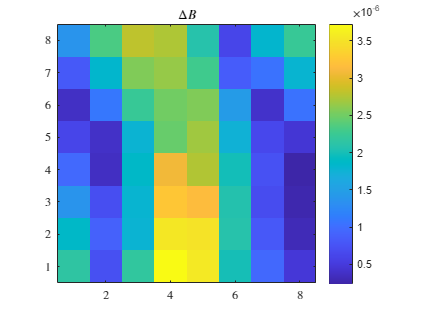

[B0,f,defects] = readMFD('data/B_defectless.txt');
assert(isempty(defects))

[B,f2,defects] = readMFD('data/B_defect_circ2mm_depth0to3.txt');
assert(all(f==f2))

delta_B = B - B0;

idx = [3 4];
f = f(idx);
delta_B = reshape(delta_B(idx,:).', size(delta_B,2), 1, []);

figure
imagesc(vecnorm(reshape(delta_B,8,8,[]), 2, 3).')
colorbar
title('$\Delta B$')
axis square xy


clear idx f2 B0 B

#### Load $\Phi$

load('data\Phi.mat', 'Phi','freqs','voxels_center')

[~,k] = ismember(f, freqs);
Phi = Phi(:,:,k);

xylim = 15e-3;
mask = -xylim < voxels_center(1,:) &  voxels_center(1,:) < xylim & ...
       -xylim < voxels_center(2,:) &  voxels_center(2,:) < xylim & ...
                                      voxels_center(3,:) > -0.6e-3;

Phi = Phi(:, mask, :);
voxels_center = voxels_center(:, mask);

y = delta_B;

Phi = cat(3, real(Phi),imag(Phi));
y   = cat(3, real(y),  imag(y)  );

clear freqs delta_B k xylim mask

#### Bernoulli Bayesian learning

tic
z = BBL(Phi, y, 'Method','WeightedPrior', 'Sparsity',0.5, 'MaxIterations',50);
fprintf("BBL uses %.2f seconds\n", toc)

BBL uses 4.35 seconds


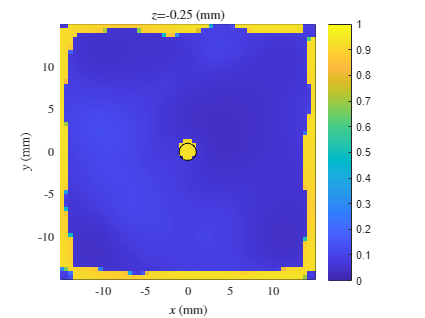


displayReconstruction(z, voxels_center, defects)

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(c, voxels_center, defects)

c = real(c);

z = unique(voxels_center(3,:));
z = sort(z, 'descend');

scale = 1e3;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = voxels_center(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    x = [min(voxels_center(1,mask)) max(voxels_center(1,mask))] * scale;
    y = [min(voxels_center(2,mask)) max(voxels_center(2,mask))] * scale;
    dx = (x(2) - x(1)) / size(c_layer,1);
    dy = (y(2) - y(1)) / size(c_layer,2);

    subplot(length(z),1,k)
    hold on
    imagesc(x, y, c_layer.', [0 1])
    colorbar
    axis square xy
    box on
    xlim(x + [-dx dx]/2)
    ylim(y + [-dy dy]/2)
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end